MorphData-mush


     HeadArea     HomerFWHMArea    NeckLength
    __________    _____________    __________
    3.3942e+05    38433            531.3     


Mushroom percentage of spines per cluster


  Columns 1 through 7
   14.1226    9.0632    8.4543   18.5324   13.7014    8.1041    8.4086
  Column 8
   16.7157


MorphData-flat


     HeadArea     HomerFWHMArea
    __________    _____________
    2.8626e+05    44099        


Stubby percentage of spines per cluster


   34.3971   12.1902   15.4576   35.1239


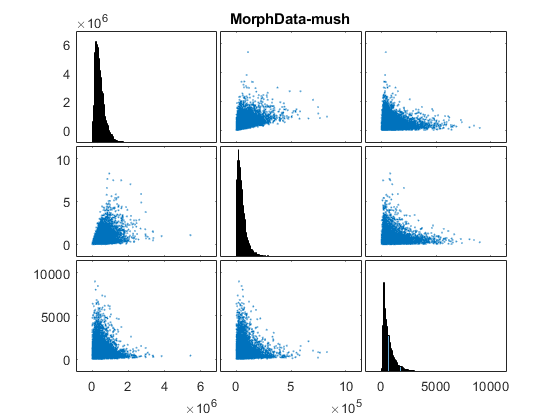

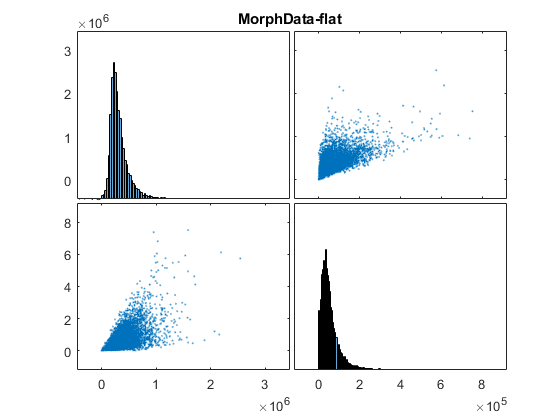

%Determine grouping thresholds
classes = {'mush', 'flat'};
cd 'Z:\user\mhelm1\Nanomap_Analysis\Data\total\_Clustering\'
% param = {'HeadArea', 'HeadHeight', 'HeadWidth', 'HomerFWHMArea', 'HomerFWHMDioDistance', 'HomerFWHMMajorAxisLength', 'HomerFWHMMinorAxisLength', 'HomerFWHMMeanIntensity', 'HomerNumber', 'NeckLength', 'NeckArea'};
param = {'HeadArea', 'HomerFWHMArea', 'NeckLength'};

for class = 1:numel(classes)
    %     Reading in data and cleanup
    data = load(['MorphData_' classes{class}]);
    field = fieldnames(data);
    data = data.(field{1});
    
    data = data(:, contains(data.Properties.VariableNames, param));
    
    data = standardizeMissing(data,Inf);
    if strcmp(classes{class}, 'flat')
        data.NeckLength = [];
    end
    
    writetable(data,['MorphData_ManualClusters_' classes{class} '.xlsx'], 'WriteVariableNames',true,'Sheet','data');
    
    figure
    plotmatrix(table2array(data));
    title(['MorphData-' classes{class}]);
    
    logdata = log10(table2array(data));
    logdata = standardizeMissing(logdata,-Inf); % to account for 0 values, which give Inf after log transform
    logdata = nanmean(logdata,1);
    logdata = 10.^logdata;
    logdata = array2table(logdata,'VariableNames',data.Properties.VariableNames);
    disp(['MorphData-' classes{class}])
    disp(logdata)
    
    writetable(logdata,['MorphData_ManualClusters_' classes{class} '.xlsx'],'Sheet','cluster_borders','WriteVariableNames',true);
    
    % Assign each file to one of the clusters
    idx = zeros(size(data,1),1);
    head_s = data.HeadArea < logdata.HeadArea;
    head_l = data.HeadArea >= logdata.HeadArea;
    homer_s = data.HomerFWHMArea < logdata.HomerFWHMArea;
    homer_l = data.HomerFWHMArea >= logdata.HomerFWHMArea;
    %     For mushroom, also create the neck classifier
    if class==1
        neck_s = data.NeckLength < logdata.NeckLength;
        neck_l = data.NeckLength >= logdata.NeckLength;
    end
    
    if class==1
        idx(all([head_s,homer_s,neck_s],2)) = 1;
        idx(all([head_l,homer_s,neck_s],2)) = 2;
        idx(all([head_s,homer_l,neck_s],2)) = 3;
        idx(all([head_l,homer_l,neck_s],2)) = 4;
        idx(all([head_s,homer_s,neck_l],2)) = 5;
        idx(all([head_l,homer_s,neck_l],2)) = 6;
        idx(all([head_s,homer_l,neck_l],2)) = 7;
        idx(all([head_l,homer_l,neck_l],2)) = 8;
        disp('Mushroom percentage of spines per cluster')
        disp(sum(idx==1:8)/size(idx,1)*100)
        writetable(array2table(sum(idx==1:8)/size(idx,1)*100,'VariableNames',sprintfc('cluster%i',1:8)),['MorphData_ManualClusters_' classes{class} '.xlsx'],'Sheet','cluster_occupancy','WriteVariableNames',true);
        csvwrite('manualclusters_mush.csv',idx)
    end
    
    if class==2
        idx(all([head_s,homer_s],2)) = 1;
        idx(all([head_l,homer_s],2)) = 2;
        idx(all([head_s,homer_l],2)) = 3;
        idx(all([head_l,homer_l],2)) = 4;
        disp('Stubby percentage of spines per cluster')
        disp(sum(idx==1:4)/size(idx,1)*100)
        writetable(array2table(sum(idx==1:4)/size(idx,1)*100,'VariableNames',sprintfc('cluster%i',1:4)),['MorphData_ManualClusters_' classes{class} '.xlsx'],'Sheet','cluster_occupancy','WriteVariableNames',true);
        csvwrite('manualclusters_flat.csv',idx)
    end
end

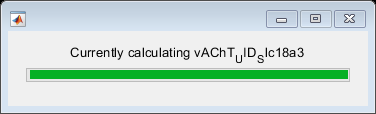

% Create cluster averages
addpath(genpath('Z:\user\mhelm1\Programming\MatLab\utilities\export_fig'));
addpath(genpath('Z:\user\mhelm1\Programming\MatLab\Colormaps'));
set(0, 'DefaultFigureColormap', inferno())
clear idx

for class = 1:numel(classes)
    if strcmp(classes{class},'mush')
        idx = csvread('manualclusters_mush.csv');
        ProteinID=load('ProteinID_mush.mat'); ProteinID=ProteinID.ProteinID_mush;
        SpotFiles=load('SpotFiles_mush.mat'); SpotFiles=SpotFiles.SpotFiles_mush;
        
    elseif strcmp(classes{class},'flat')
        idx = csvread('manualclusters_flat.csv');
        ProteinID=load('ProteinID_flat.mat'); ProteinID=ProteinID.ProteinID_flat;
        SpotFiles=load('SpotFiles_flat.mat'); SpotFiles=SpotFiles.SpotFiles_flat;
    end
    
    proteinnames=ProteinID.Properties.VariableNames;
    w=waitbar(0,'Please wait...');
    
    for protein=1:size(proteinnames,2)
        waitbar(protein/size(proteinnames,2),w,['Currently calculating ' proteinnames{protein}]);
        
        %     Create a results folder for the protein
        if ~exist(['ClusterAverages' filesep proteinnames{protein}],'dir')
            mkdir(['ClusterAverages' filesep proteinnames{protein}]);
        end
        
        clear mess* spots cluster_id path coord* lib* dio* homer* sted*
        
        %     get the spot files and cluster memberships of spines analyzed for this protein
        spots=SpotFiles(ProteinID.(proteinnames{protein})==1);
        cluster_id=idx(ProteinID.(proteinnames{protein})==1);
        
        %% Create a library that links a spot file to its corresponding aligned images.
        
        % get the two folder names from the spot files
        path=regexp(spots,'\','split');
        path=cellfun(@(x) x(end-1),path,'UniformOutput',0);
        path=[path{:}]';
        path=unique(path,'stable');
      
        coord1=load(['Z:\user\mhelm1\Nanomap_Analysis\Data\Replicate1' filesep path{1} filesep 'coordinates.mat']);
        coord1=coord1.coordinates;
        
        [~,mess_spots_rep1]=fileattrib(['Z:\user\mhelm1\Nanomap_Analysis\Data\Replicate1' filesep path{1} filesep '*_spots*.txt']);
        [~,order]=sort({mess_spots_rep1.Name});mess_spots_rep1=mess_spots_rep1(order);order=[]; %sort to avoid unordered spot files due to server bugs
        mess_spots_rep1=mess_spots_rep1(coord1.classification==class);
        classification1=coord1.classification;
        classification1(classification1==4)=[];
        [~,mess_dio_rep1]=fileattrib(['Z:\user\mhelm1\Nanomap_Analysis\Data\Replicate1' filesep path{1} filesep '*dio_aligned_150px_myfilt*.txt']);
        mess_dio_rep1=natsort({mess_dio_rep1.Name});
        mess_dio_rep1(classification1~=class)=[];
        [~,mess_homer_rep1]=fileattrib(['Z:\user\mhelm1\Nanomap_Analysis\Data\Replicate1' filesep path{1} filesep 'homer_aligned_150px_myfilt*.txt']);
        mess_homer_rep1=natsort({mess_homer_rep1.Name});
        mess_homer_rep1(classification1~=class)=[];
        [~,mess_sted_rep1]=fileattrib(['Z:\user\mhelm1\Nanomap_Analysis\Data\Replicate1' filesep path{1} filesep 'sted_aligned_150px_myfilt*.txt']);
        mess_sted_rep1=natsort({mess_sted_rep1.Name});
        mess_sted_rep1(classification1~=class)=[];
        lib_rep1=cat(2,{mess_spots_rep1.Name}',mess_dio_rep1',mess_homer_rep1',mess_sted_rep1');
        
        
        coord2=load(['Z:\user\mhelm1\Nanomap_Analysis\Data\Replicate2' filesep path{2} filesep 'coordinates.mat']);
        coord2=coord2.coordinates;
        
        [~,mess_spots_rep2]=fileattrib(['Z:\user\mhelm1\Nanomap_Analysis\Data\Replicate2' filesep path{2} filesep '*_spots*.txt']);
        [~,order]=sort({mess_spots_rep2.Name});mess_spots_rep2=mess_spots_rep2(order);order=[]; %sort to avoid unordered spot files due to server bugs
        mess_spots_rep2=mess_spots_rep2(coord2.classification==class);
        classification2=coord2.classification;
        classification2(classification2==4)=[];
        [~,mess_dio_rep2]=fileattrib(['Z:\user\mhelm1\Nanomap_Analysis\Data\Replicate2' filesep path{2} filesep 'dio_aligned_150px_myfilt*.txt']);
        mess_dio_rep2=natsort({mess_dio_rep2.Name});
        mess_dio_rep2(classification2~=class)=[];
        [~,mess_homer_rep2]=fileattrib(['Z:\user\mhelm1\Nanomap_Analysis\Data\Replicate2' filesep path{2} filesep 'homer_aligned_150px_myfilt*.txt']);
        mess_homer_rep2=natsort({mess_homer_rep2.Name});
        mess_homer_rep2(classification2~=class)=[];
        [~,mess_sted_rep2]=fileattrib(['Z:\user\mhelm1\Nanomap_Analysis\Data\Replicate2' filesep path{2} filesep 'sted_aligned_150px_myfilt*.txt']);
        mess_sted_rep2=natsort({mess_sted_rep2.Name});
        mess_sted_rep2(classification2~=class)=[];
        lib_rep2=cat(2,{mess_spots_rep2.Name}',mess_dio_rep2',mess_homer_rep2',mess_sted_rep2');
        lib=cat(1,lib_rep1,lib_rep2);
        
        
        %% Loop over the cluster IDs and find all spots that correspond to the cluster for the protein. Average them
                    unique_ids = unique(cluster_id);
        for i=1:numel(unique_ids)
            cluster_idx = unique_ids(i);
            spots_cluster=spots(cluster_id==cluster_idx);
            dio=zeros(151,151,numel(spots_cluster));
            homer=zeros(151,151,numel(spots_cluster));
            sted=zeros(151,151,numel(spots_cluster));
            for j=1:numel(spots_cluster)
                spots_avg_num=find(contains(lib(:,1),spots_cluster{j}));
                dio(:,:,j)=dlmread(lib{spots_avg_num,2});
                homer(:,:,j)=dlmread(lib{spots_avg_num,3});
                sted(:,:,j)=dlmread(lib{spots_avg_num,4});
            end
            
            save(['ClusterAverages' filesep proteinnames{protein} filesep 'CombinedImageStack_' classes{class} '_dio_cluster' num2str(cluster_idx) '.mat'],'dio');
            save(['ClusterAverages' filesep proteinnames{protein} filesep 'CombinedImageStack_' classes{class} '_homer_cluster' num2str(cluster_idx) '.mat'],'homer');
            save(['ClusterAverages' filesep proteinnames{protein} filesep 'CombinedImageStack_' classes{class} '_sted_cluster' num2str(cluster_idx) '.mat'],'sted');
            
            dio_avg=mean(dio,3);
            homer_avg=mean(homer,3);
            sted_avg=mean(sted,3);
            
            dlmwrite(['ClusterAverages' filesep proteinnames{protein} filesep proteinnames{protein} '_' classes{class} '_dio_cluster' num2str(cluster_idx) '.txt'],dio_avg);
            dlmwrite(['ClusterAverages' filesep proteinnames{protein} filesep proteinnames{protein} '_' classes{class} '_homer_cluster' num2str(cluster_idx) '.txt'],homer_avg);
            dlmwrite(['ClusterAverages' filesep proteinnames{protein} filesep proteinnames{protein} '_' classes{class} '_sted_cluster' num2str(cluster_idx) '.txt'],sted_avg);
            
            f1=figure('Visible','off');
            imagesc(dio_avg);
            axis equal;
            axis off;
            export_fig(['ClusterAverages' filesep proteinnames{protein} filesep proteinnames{protein} '_' classes{class} '_dio_cluster' num2str(cluster_idx)], '-png', '-pdf', '-q101', '-transparent');
            close(f1);
            
            f1=figure('Visible','off');
            imagesc(homer_avg);
            axis equal;
            axis off;
            export_fig(['ClusterAverages' filesep proteinnames{protein} filesep proteinnames{protein} '_' classes{class} '_homer_cluster' num2str(cluster_idx)], '-png', '-pdf', '-q101', '-transparent');
            close(f1);
            
            f1=figure('Visible','off');
            imagesc(sted_avg);
            axis equal;
            axis off;
            export_fig(['ClusterAverages' filesep proteinnames{protein} filesep proteinnames{protein} '_' classes{class} '_sted_cluster' num2str(cluster_idx)], '-png', '-pdf', '-q101', '-transparent');
            close(f1)
        end
    end
end

%Analyse cluster averages
clear all
warning('off','MATLAB:xlswrite:AddSheet')
warning('off','MATLAB:table:RowsAddedExistingVars')

classes = {'mush', 'flat'};
zones_mush=double(imread('Z:\user\mhelm1\Nanomap_Analysis\Matlab\ZoneAnalysis\mushroom_zones_plus_background.tif'));
zones_flat=double(imread('Z:\user\mhelm1\Nanomap_Analysis\Matlab\ZoneAnalysis\flat_thin_zones_plus_background.tif'));
zones_mush_avg = dlmread('Z:\user\mhelm1\Nanomap_Analysis\Matlab\ZoneAnalysis\Mush_ZoneEnrichment_avg_nonnormalized.txt');
zones_flat_avg = dlmread('Z:\user\mhelm1\Nanomap_Analysis\Matlab\ZoneAnalysis\Flat_ZoneEnrichment_avg_nonnormalized.txt');

cd_path='Z:\user\mhelm1\Nanomap_Analysis\Data\total\_Clustering\ClusterAverages';
folders = getfolders(cd_path);

for folder = 1:numel(folders)
    cd([cd_path filesep folders{folder}])
    UID = regexp(folders{folder}, '(?<=UID_)[a-zA-Z0-9]*', 'match');
    total_folders = getfolders('Z:\user\mhelm1\Nanomap_Analysis\Data\total');
    total_folders(~contains(total_folders,['UID-' char(UID)])) = [];
    total_folders = char(total_folders);
    %     T_mush_foldoveravg=table();
    %     T_flat_foldoveravg=table();
    %     T_mush_foldoveravg_sd=table();
    %     T_flat_foldoveravg_sd=table();
    %     T_mush_foldoveravg_sem=tabletotal_folders
    %     T_flat_foldoveravg_sem=table();
    
    for class = 1:numel(classes)
        clusters = dir(['CombinedImageStack_' classes{class} '_sted_cluster*.mat']);
        clusters = {clusters.name};
        cluster_idx = cellfun(@(x)regexp(x,'(?<=cluster)\d+','match'),clusters);
        cluster_idx = cellfun(@(x)['cluster' x],cluster_idx,'UniformOutput',false);
        
        if strcmp(classes{class},'mush')
            zone_def = zones_mush;
load(['Z:\user\mhelm1\Nanomap_Analysis\Data\total' filesep total_folders filesep 'CombinedImageStack_Mush_sted_150px_myfilt.mat']);

        elseif strcmp(classes{class},'flat')
            zone_def = zones_flat;
           load(['Z:\user\mhelm1\Nanomap_Analysis\Data\total' filesep total_folders filesep 'CombinedImageStack_Flat_sted_150px_myfilt.mat']);
     else
            disp('Error in class selection!')
            break
        end
        
        cluster_intensities_spine = {};
        cluster_intensities_PSD = {};
        
        for cluster = 1:numel(clusters)
            load(clusters{cluster})
            %             for each cluster determine relative change of protein intensity to mean (= intensity of all spines of this protein together across clusters)
            intensities_spine = [];
            intensities_spine = sted.*(zone_def<16);
            intensities_spine = reshape(intensities_spine,[size(sted,1)*size(sted,2), size(sted,3)]);
            intensities_spine = sum(intensities_spine,1);
            intensities_mean = img_both.*(zone_def<16);
            intensities_mean = reshape(intensities_mean,[size(img_both,1)*size(img_both,2),size(img_both,3)]);
            intensities_mean = sum(intensities_mean,1);
            intensities_spine = intensities_spine/mean(intensities_mean);
            cluster_intensities_spine{1,cluster} = intensities_spine';
            
            intensities_PSD = [];
            intensities_PSD = sted.*(zone_def<4);
            intensities_PSD = reshape(intensities_PSD,[size(sted,1)*size(sted,2), size(sted,3)]);
            intensities_PSD = sum(intensities_PSD,1);
            intensities_mean = img_both.*(zone_def<4);
            intensities_mean = reshape(intensities_mean,[size(img_both,1)*size(img_both,2),size(img_both,3)]);
            intensities_mean = sum(intensities_mean,1);
            intensities_PSD = intensities_PSD/mean(intensities_mean);
            cluster_intensities_PSD{1,cluster} = intensities_PSD';
            
            
            %             Determine Zone Enrichment for each cluster
            
            %             if strcmp(classes{class},'mush')
            %
            %                 for zone=1:15%max(zones_mush(:))
            %                     temp=[];
            %                     for k=1:size(sted,3)
            %                         z=sted(:,:,k);
            %                         temp=cat(1,temp,nansum(z(zone_def==zone))/nansum(z(zone_def<16)));
            %                     end
            %                     temp=temp/sum(zone_def(:)==zone);
            %                     temp=(temp-zones_mush_avg(zone))/zones_mush_avg(zone);
            %                     T_mush_foldoveravg{cluster,zone}=nanmean(temp);
            %                     T_mush_foldoveravg_sd{cluster,zone}=nanstd(temp);
            %                     T_mush_foldoveravg_sem{cluster,zone}=nanstd(temp)/sqrt(length(temp));
            %                 end
            %
            %             elseif strcmp(classes{class},'flat')
            %                 for zone=1:11%max(zones_flat(:))
            %                     temp=[];
            %                     for k=1:size(sted,3)
            %                         z=sted(:,:,k);
            %                         %                 temp=cat(1,temp,z(zones_flat==j));
            %                         temp=cat(1,temp,nansum(z(zone_def==zone))/nansum(z(zone_def<16)));
            %                     end
            %                     temp=temp/sum(zone_def(:)==zone);
            %                     temp=(temp-zones_flat_avg(zone))/zones_flat_avg(zone);
            %                     T_flat_foldoveravg{cluster,zone}=nanmean(temp);
            %                     T_flat_foldoveravg_sd{cluster,zone}=nanstd(temp);
            %                     T_flat_foldoveravg_sem{cluster,zone}=nanstd(temp)/sqrt(length(temp));
            %                 end
            %             end
            %
        end
        
        
        if numel(clusters)>1
            cluster_intensities_spine = padcat(cluster_intensities_spine{:});
            cluster_intensities_PSD = padcat(cluster_intensities_PSD{:});
        elseif numel(cluster)==1
            cluster_intensities_spine = [cluster_intensities_spine{:}];
            cluster_intensities_PSD = [cluster_intensities_PSD{:}];
        else
            break
        end
        cluster_intensities_spine = array2table(cluster_intensities_spine,'VariableNames',cluster_idx);
        cluster_intensities_PSD = array2table(cluster_intensities_PSD,'VariableNames',cluster_idx);
        
        if strcmp(classes{class},'mush')
            writetable(cluster_intensities_spine,[cd_path filesep folders{folder} filesep 'ClusterIntensities.xlsx'],'WriteVariableNames',1,'Sheet','mush_spine');
            writetable(cluster_intensities_PSD,[cd_path filesep folders{folder} filesep 'ClusterIntensities.xlsx'],'WriteVariableNames',1,'Sheet','mush_PSD');
            %             T_mush_foldoveravg.Properties.RowNames=cluster_idx;
            %             T_mush_foldoveravg_sd.Properties.RowNames=cluster_idx;
            %             T_mush_foldoveravg_sem.Properties.RowNames=cluster_idx;
            %             T_mush_foldoveravg.Properties.VariableNames=sprintfc('Zone%i',1:15);
            %             T_mush_foldoveravg_sd.Properties.VariableNames=sprintfc('Zone%i',1:15);
            %             T_mush_foldoveravg_sem.Properties.VariableNames=sprintfc('Zone%i',1:15);
        elseif strcmp(classes{class},'flat')
            writetable(cluster_intensities_spine,[cd_path filesep folders{folder} filesep 'ClusterIntensities.xlsx'],'WriteVariableNames',1,'Sheet','flat_spine');
            writetable(cluster_intensities_PSD,[cd_path filesep folders{folder} filesep 'ClusterIntensities.xlsx'],'WriteVariableNames',1,'Sheet','flat_PSD');
            %             T_flat_foldoveravg.Properties.RowNames=cluster_idx;
            %             T_flat_foldoveravg_sd.Properties.RowNames=cluster_idx;
            %             T_flat_foldoveravg_sem.Properties.RowNames=cluster_idx;
            %             T_flat_foldoveravg.Properties.VariableNames=sprintfc('Zone%i',1:11);
            %             T_flat_foldoveravg_sd.Properties.VariableNames=sprintfc('Zone%i',1:11);
            %             T_flat_foldoveravg_sem.Properties.VariableNames=sprintfc('Zone%i',1:11);
        end
    end
    
    %     save([cd_path filesep folders{folder} filesep 'ProteinZoneEnrichment_mush_FoldOverAvg.mat'],'T_mush_foldoveravg');
    %     save([cd_path filesep folders{folder} filesep 'ProteinZoneEnrichment_flat_FoldOverAvg.mat'],'T_flat_foldoveravg');
    %     save([cd_path filesep folders{folder} filesep 'ProteinZoneEnrichment_mush_FoldOverAvg_sd.mat'],'T_mush_foldoveravg_sd');
    %     save([cd_path filesep folders{folder} filesep 'ProteinZoneEnrichment_flat_FoldOverAvg_sd.mat'],'T_flat_foldoveravg_sd');
    %     save([cd_path filesep folders{folder} filesep 'ProteinZoneEnrichment_mush_FoldOverAvg_sem.mat'],'T_mush_foldoveravg_sem');
    %     save([cd_path filesep folders{folder} filesep 'ProteinZoneEnrichment_flat_FoldOverAvg_sem.mat'],'T_flat_foldoveravg_sem');
    %
    %     writetable(T_mush_foldoveravg,[cd_path filesep folders{folder} filesep 'ProteinZoneEnrichment_mush_FoldOverAvg.xlsx'],'WriteVariableNames',1,'WriteRowNames',1,'Sheet','data');
    %     writetable(T_flat_foldoveravg,[cd_path filesep folders{folder} filesep 'ProteinZoneEnrichment_flat_FoldOverAvg.xlsx'],'WriteVariableNames',1,'WriteRowNames',1,'Sheet','data');
    %     writetable(T_mush_foldoveravg_sd,[cd_path filesep folders{folder} filesep 'ProteinZoneEnrichment_mush_FoldOverAvg.xlsx'],'WriteVariableNames',1,'WriteRowNames',1,'Sheet','sd');
    %     writetable(T_flat_foldoveravg_sd,[cd_path filesep folders{folder} filesep 'ProteinZoneEnrichment_flat_FoldOverAvg.xlsx'],'WriteVariableNames',1,'WriteRowNames',1,'Sheet','sd');
    %     writetable(T_mush_foldoveravg_sem,[cd_path filesep folders{folder} filesep 'ProteinZoneEnrichment_mush_FoldOverAvg.xlsx'],'WriteVariableNames',1,'WriteRowNames',1,'Sheet','sem');
    %     writetable(T_flat_foldoveravg_sem,[cd_path filesep folders{folder} filesep 'ProteinZoneEnrichment_flat_FoldOverAvg.xlsx'],'WriteVariableNames',1,'WriteRowNames',1,'Sheet','sem');
end

% compile all the intensity data into one big table for comparison and plotting. Column is proteins, rows = clusters.
cluster_total_mush_spine = nan([numel(folders),8*3]);
cluster_total_mush_PSD = nan([numel(folders),8*3]);
cluster_total_flat_spine = nan([numel(folders),4*3]);
cluster_total_flat_PSD = nan([numel(folders),4*3]);

for folder = 1:numel(folders)
    cd([cd_path filesep folders{folder}])
    for class = 1:numel(classes)
        
        if strcmp(classes{class},'mush')
            cluster_intensities_spine = readtable([cd_path filesep folders{folder} filesep 'ClusterIntensities.xlsx'],'ReadVariableNames',1,'Sheet','mush_spine');
            cluster_intensities_PSD = readtable([cd_path filesep folders{folder} filesep 'ClusterIntensities.xlsx'],'ReadVariableNames',1,'Sheet','mush_PSD');
            cluster_max = 8;
        elseif strcmp(classes{class},'flat')
            cluster_intensities_spine = readtable([cd_path filesep folders{folder} filesep 'ClusterIntensities.xlsx'],'ReadVariableNames',1,'Sheet','flat_spine');
            cluster_intensities_PSD = readtable([cd_path filesep folders{folder} filesep 'ClusterIntensities.xlsx'],'ReadVariableNames',1,'Sheet','flat_PSD');
            cluster_max = 4;
        end
        
        for cluster = 1:cluster_max
            if sum(strcmp(cluster_intensities_spine.Properties.VariableNames,['cluster' num2str(cluster)])) == 0
                %                If there is no spine in the cluster keep the nans in the file and go to the next cluster
                continue
            end
            
            mean_spine = nanmean(cluster_intensities_spine{:,['cluster' num2str(cluster)]});
            sd_spine = nanstd(cluster_intensities_spine{:,['cluster' num2str(cluster)]});
            n_spine = cluster_intensities_spine{:,['cluster' num2str(cluster)]};
            n_spine(isnan(n_spine)) = [];
            n_spine = numel(n_spine);
            
            mean_PSD = nanmean(cluster_intensities_PSD{:,['cluster' num2str(cluster)]});
            sd_PSD = nanstd(cluster_intensities_PSD{:,['cluster' num2str(cluster)]});
            n_PSD = cluster_intensities_PSD{:,['cluster' num2str(cluster)]};
            n_PSD(isnan(n_PSD)) = [];
            n_PSD = numel(n_PSD);
            
            if strcmp(classes{class},'mush')
                cluster_total_mush_spine(folder,cluster*3-2:cluster*3) = [mean_spine, sd_spine, n_spine];
                cluster_total_mush_PSD(folder,cluster*3-2:cluster*3) = [mean_PSD, sd_PSD, n_PSD];
            elseif strcmp(classes{class},'flat')
                cluster_total_flat_spine(folder,cluster*3-2:cluster*3) = [mean_spine, sd_spine, n_spine];
                cluster_total_flat_PSD(folder,cluster*3-2:cluster*3) = [mean_PSD, sd_PSD, n_PSD];
            end
        end
    end
end

param = {'mean', 'SD', 'N'};

%create median normalized data
cluster_total_mush_spine_mediannorm = nanmedian(cluster_total_mush_spine,1);
cluster_total_mush_spine_mediannorm(2:3:23) = 1; %do not normalize SD and N
cluster_total_mush_spine_mediannorm(3:3:24) = 1;
cluster_total_mush_spine_mediannorm = cluster_total_mush_spine ./ cluster_total_mush_spine_mediannorm;
cluster_total_mush_spine_mediannorm(:,2:3:23) = (cluster_total_mush_spine(:,2:3:23) ./ cluster_total_mush_spine(:,1:3:22)) .* cluster_total_mush_spine_mediannorm(:,1:3:22);

cluster_total_mush_PSD_mediannorm = nanmedian(cluster_total_mush_PSD,1);
cluster_total_mush_PSD_mediannorm(2:3:23) = 1; %do not normalize SD and N
cluster_total_mush_PSD_mediannorm(3:3:24) = 1;
cluster_total_mush_PSD_mediannorm = cluster_total_mush_PSD ./ cluster_total_mush_PSD_mediannorm;
cluster_total_mush_PSD_mediannorm(:,2:3:23) = (cluster_total_mush_PSD(:,2:3:23) ./ cluster_total_mush_PSD(:,1:3:22)) .* cluster_total_mush_PSD_mediannorm(:,1:3:22);

cluster_total_flat_spine_mediannorm = nanmedian(cluster_total_flat_spine,1);
cluster_total_flat_spine_mediannorm(2:3:11) = 1; %do not normalize SD and N
cluster_total_flat_spine_mediannorm(3:3:12) = 1;
cluster_total_flat_spine_mediannorm = cluster_total_flat_spine ./ cluster_total_flat_spine_mediannorm;
cluster_total_flat_spine_mediannorm(:,2:3:11) = (cluster_total_flat_spine(:,2:3:11) ./ cluster_total_flat_spine(:,1:3:10)) .* cluster_total_flat_spine_mediannorm(:,1:3:10);

cluster_total_flat_PSD_mediannorm = nanmedian(cluster_total_flat_PSD,1);
cluster_total_flat_PSD_mediannorm(2:3:11) = 1; %do not normalize SD and N
cluster_total_flat_PSD_mediannorm(3:3:12) = 1;
cluster_total_flat_PSD_mediannorm = cluster_total_flat_PSD ./ cluster_total_flat_PSD_mediannorm;
cluster_total_flat_PSD_mediannorm(:,2:3:11) = (cluster_total_flat_PSD(:,2:3:11) ./ cluster_total_flat_PSD(:,1:3:10)) .* cluster_total_flat_PSD_mediannorm(:,1:3:10);

% Convert to table, fill Nans with 0 and save
cluster_total_mush_spine = array2table(cluster_total_mush_spine,'VariableNames',strinterweave(sprintfc('cluster%i',1:8)',param,'_'),'RowNames',folders);
cluster_total_mush_PSD = array2table(cluster_total_mush_PSD,'VariableNames',strinterweave(sprintfc('cluster%i',1:8)',param,'_'),'RowNames',folders);
cluster_total_flat_spine = array2table(cluster_total_flat_spine,'VariableNames',strinterweave(sprintfc('cluster%i',1:4)',param,'_'),'RowNames',folders);
cluster_total_flat_PSD = array2table(cluster_total_flat_PSD,'VariableNames',strinterweave(sprintfc('cluster%i',1:4)',param,'_'),'RowNames',folders);

cluster_total_mush_spine = fillmissing(cluster_total_mush_spine,'constant',0);
cluster_total_mush_PSD = fillmissing(cluster_total_mush_PSD,'constant',0);
cluster_total_flat_spine = fillmissing(cluster_total_flat_spine,'constant',0);
cluster_total_flat_PSD = fillmissing(cluster_total_flat_PSD,'constant',0);

writetable(cluster_total_mush_spine,'Z:\user\mhelm1\Nanomap_Analysis\Data\total\_Clustering\ClusterAverages\ClusterTotalIntensities.xlsx','WriteRowNames',1,'WriteVariableNames',1,'Sheet','mush_spine');
writetable(cluster_total_mush_PSD,'Z:\user\mhelm1\Nanomap_Analysis\Data\total\_Clustering\ClusterAverages\ClusterTotalIntensities.xlsx','WriteRowNames',1,'WriteVariableNames',1,'Sheet','mush_PSD');
writetable(cluster_total_flat_spine,'Z:\user\mhelm1\Nanomap_Analysis\Data\total\_Clustering\ClusterAverages\ClusterTotalIntensities.xlsx','WriteRowNames',1,'WriteVariableNames',1,'Sheet','flat_spine');
writetable(cluster_total_flat_PSD,'Z:\user\mhelm1\Nanomap_Analysis\Data\total\_Clustering\ClusterAverages\ClusterTotalIntensities.xlsx','WriteRowNames',1,'WriteVariableNames',1,'Sheet','flat_PSD');
writetable(array2table(folders),'Z:\user\mhelm1\Nanomap_Analysis\Data\total\_Clustering\ClusterAverages\ClusterTotalIntensities.xlsx','WriteVariableNames',0,'Sheet','names');


%save in separate sheets
cluster_total_mush_spine_mediannorm = array2table(cluster_total_mush_spine_mediannorm,'VariableNames',strinterweave(sprintfc('cluster%i',1:8)',param,'_'),'RowNames',folders);
cluster_total_mush_PSD_mediannorm = array2table(cluster_total_mush_PSD_mediannorm,'VariableNames',strinterweave(sprintfc('cluster%i',1:8)',param,'_'),'RowNames',folders);
cluster_total_flat_spine_mediannorm = array2table(cluster_total_flat_spine_mediannorm,'VariableNames',strinterweave(sprintfc('cluster%i',1:4)',param,'_'),'RowNames',folders);
cluster_total_flat_PSD_mediannorm = array2table(cluster_total_flat_PSD_mediannorm,'VariableNames',strinterweave(sprintfc('cluster%i',1:4)',param,'_'),'RowNames',folders);

cluster_total_mush_spine_mediannorm = fillmissing(cluster_total_mush_spine_mediannorm,'constant',0);
cluster_total_mush_PSD_mediannorm = fillmissing(cluster_total_mush_PSD_mediannorm,'constant',0);
cluster_total_flat_spine_mediannorm = fillmissing(cluster_total_flat_spine_mediannorm,'constant',0);
cluster_total_flat_PSD_mediannorm = fillmissing(cluster_total_flat_PSD_mediannorm,'constant',0);

writetable(cluster_total_mush_spine_mediannorm,'Z:\user\mhelm1\Nanomap_Analysis\Data\total\_Clustering\ClusterAverages\ClusterTotalIntensities.xlsx','WriteRowNames',1,'WriteVariableNames',1,'Sheet','mush_spine_mediannorm');
writetable(cluster_total_mush_PSD_mediannorm,'Z:\user\mhelm1\Nanomap_Analysis\Data\total\_Clustering\ClusterAverages\ClusterTotalIntensities.xlsx','WriteRowNames',1,'WriteVariableNames',1,'Sheet','mush_PSD_mediannorm');
writetable(cluster_total_flat_spine_mediannorm,'Z:\user\mhelm1\Nanomap_Analysis\Data\total\_Clustering\ClusterAverages\ClusterTotalIntensities.xlsx','WriteRowNames',1,'WriteVariableNames',1,'Sheet','flat_spine_mediannorm');
writetable(cluster_total_flat_PSD_mediannorm,'Z:\user\mhelm1\Nanomap_Analysis\Data\total\_Clustering\ClusterAverages\ClusterTotalIntensities.xlsx','WriteRowNames',1,'WriteVariableNames',1,'Sheet','flat_PSD_mediannorm');

warning('on','MATLAB:xlswrite:AddSheet')
warning('on','MATLAB:table:RowsAddedExistingVars')